## Parametros

El eje fijo se deja en:

punto_fijo = [0; 0];

El centro del trebol estará ubicado en (se escogió arbitrariamente):

centro_trebol = [25; 25];

 Con esto, necesitamos que los eslabones en máxima estensión midan al menos:

lado_trebol_max = 15*1.33;
diagonal_max = hypot(lado_trebol_max, lado_trebol_max);
radio_punto_max = hypot(centro_trebol(1), centro_trebol(2)) + diagonal_max/2;

Se escogen como primera aproximación para la longitud de los eslabones:

largo_eslabon_1 = 30;
largo_eslabon_2 = 20;

El punto máximo al que llegarán estos eslabones es:

radio_alcance_max = largo_eslabon_1+largo_eslabon_2;

Con esto, es posible llegar a todos los puntos de la trayectoria con las longitudes escogidas para los eslabones. Y se deja una tolerancia de [cm]:

radio_tolerancia = radio_alcance_max - radio_punto_max;

Se fijan los valores de a y b para que el trebol mida 15cm de lado y esté sin rotar (esto se usa más adelante, en el modelo del trebol):

a_min = 1.332;
b_no_rot = 4.71;

Para ajustar la escala y rotación del trebol:

escala = 1; % default = 1
rotacion = 0; % en radianes
a = a_min * escala;
b = b_no_rot + rotacion;

## Puntas de los eslabones a partir de angulos

syms theta_1;
syms theta_2;

La ubicación de las puntas de los eslabones estará dada por las siguientes expresiones, en donde B es la herramienta de trabajo:

a_x(theta_1) = punto_fijo(1)+largo_eslabon_1*cos(theta_1);
a_y(theta_1) = punto_fijo(2)+largo_eslabon_1*sin(theta_1);
b_x(theta_1, theta_2) = a_x+largo_eslabon_2*cos(theta_1+theta_2);
b_y(theta_1, theta_2) = a_y+largo_eslabon_2*sin(theta_1+theta_2);

## Angulos a partir de posición de B

theta_1_fn_a_x = finverse(a_x); % en la función resultante theta_1 en realidad es a_x
theta_1_fn_a_y = finverse(a_y); % en la función resultante theta_1 en realidad es a_y
theta_2_fn_b_x = finverse(b_x, theta_2); % en la función resultante theta_2 en realidad es b_x
theta_2_fn_b_y = finverse(b_y, theta_2); % en la función resultante theta_2 en realidad es b_y

## Gráfica

Valores de prueba:

a_x_d = 0;
a_y_d = 30;
b_x_d = 20;
b_y_d = 30;

theta_1_x = theta_1_fn_a_x(a_x_d);
theta_1_y = theta_1_fn_a_y(a_y_d);
theta_2_x = theta_2_fn_b_x(theta_1_fn_a_x(a_x_d), b_x_d);
theta_2_y = theta_2_fn_b_y(theta_1_fn_a_y(a_y_d), b_y_d);

theta_1_prueba = 0;
theta_2_prueba = 0;
if theta_1_x == theta_1_y
    theta_1_prueba = theta_1_x;
end
if theta_2_x == theta_2_y
    theta_2_prueba = theta_2_x;
end

A = [a_x(theta_1_prueba); a_y(theta_1_prueba)];
B = [b_x(theta_1_prueba, theta_2_prueba); b_y(theta_1_prueba, theta_2_prueba)];

Gráfica:

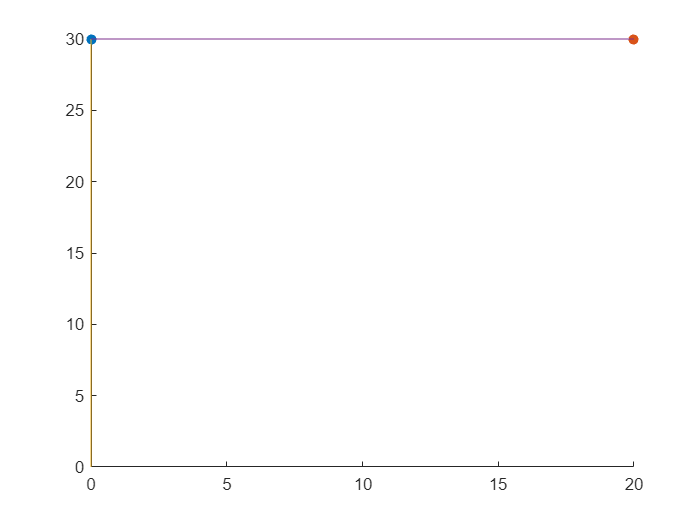

scatter(A(1), A(2), 'filled');
hold on;
scatter(B(1), B(2), 'filled');
plot([punto_fijo(1) A(1)], [punto_fijo(2) A(2)])
plot([A(1) B(1)], [A(2) B(2)])
hold off;

## Cartesian-Space trajectory planning

Usaremos interpolation-based Cartesian-space planning.

### Definir la trayectoria

syms theta_trebol;
trebol_x(theta_trebol) = (a*(sin(4*theta_trebol+b)+6)).*cos(theta_trebol)+centro_trebol(1);
trebol_y(theta_trebol) = (a*(sin(4*theta_trebol+b)+6)).*sin(theta_trebol)+centro_trebol(2);

### Discretización de la trayectoria

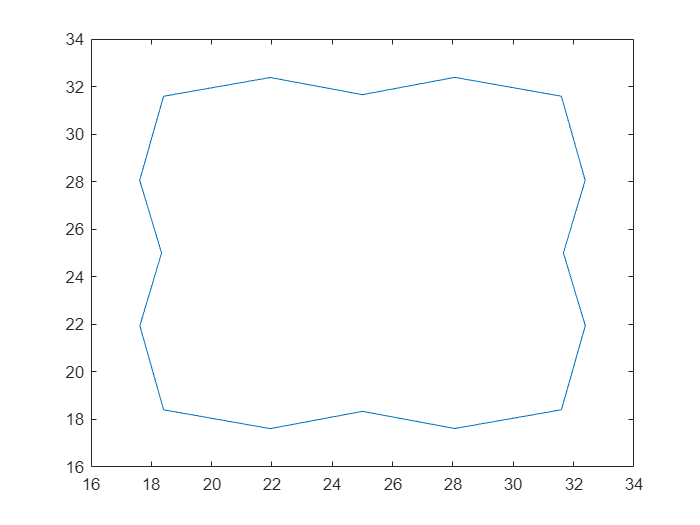

intervalo_theta_trebol = pi/8;
theta_trebol_discreto = 0:intervalo_theta_trebol:2*pi;
trebol_discretizado = [trebol_x(theta_trebol_discreto); trebol_y(theta_trebol_discreto)];
plot(trebol_discretizado(1,:), trebol_discretizado(2,:))